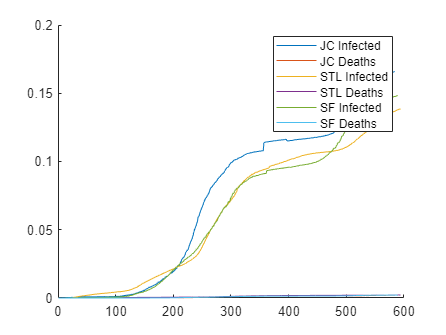

% Here is an example that reads in infection and fatalities from STL City
% and loads them into a new matrix covidstlcity_full
% In addition to this, you have other matrices for the other two regions in question
% DEBUG

% load covid data into variable
base_data = load("COVIDdata.mat");

coviddata = load("COVIDdata.mat");
casedata = coviddata.COVID_MO;
pops = containers.Map({'Jefferson City','St. Louis','Springfield'},[150198,2805473,475220]);
start = 300;
t = 273; % TO SPECIFY
% get Jefferson City data
jc_data = coviddata.COVID_MO(coviddata.COVID_MO.groupID==1,setdiff(1:4,2));
jc = table2array(jc_data(:,2:3))./pops('Jefferson City');
% get Jefferson City data
stl_data = coviddata.COVID_MO(coviddata.COVID_MO.groupID==2,setdiff(1:4,2));
stl = table2array(stl_data(:,2:3));
stl = stl./pops('St. Louis');
sf_data = coviddata.COVID_MO(coviddata.COVID_MO.groupID==3,setdiff(1:4,2));
sf = table2array(sf_data(:,2:3))./pops('Springfield');

% create graph
figure;
hold on
plot(jc)
plot(stl)
plot(sf)
legend('JC Infected', 'JC Deaths', 'STL Infected', 'STL Deaths', 'SF Infected', 'SF Deaths')
hold off

coviddata = stl(start:start+t-1,:);


% The following line creates an 'anonymous' function that will return the cost (i.e., the model fitting error) given a set
% of parameters.  There are some technical reasons for setting this up in this way.
% Feel free to peruse the MATLAB help at
% https://www.mathworks.com/help/optim/ug/fmincon.html
% and see the sectiono on 'passing extra arguments'
% Basically, 'sirafun' is being set as the function siroutput (which you
% will be designing) but with t and coviddata specified.
sirafun= @(x)siroutput(x,t,coviddata);

## set up rate and initial condition constraints

Set A and b to impose a parameter inequality constraint of the form A*x < b Note that this is imposed element-wise If you don't want such a constraint, keep these matrices empty.

A = [];
b = [];

## set up some fixed constraints

Set Af and bf to impose a parameter constraint of the form Af*x = bf Hint: For example, the sum of the initial conditions should be constrained If you don't want such a constraint, keep these matrices empty.

Af = [];
bf = [];

## set up upper and lower bound constraints

Set upper and lower bounds on the parameters lb < x < ub here, the inequality is imposed element-wise If you don't want such a constraint, keep these matrices empty.

ub = ones(1,7)';
lb = zeros(1,7)';

% Specify some initial parameters for the optimizer to start from
% Inf; Fat; Rec; Susc; Inf; Rec; Fat
x0 = [0.02 0.01 0.3 .98 .02 0 0]

x0 =     0.0200    0.0100    0.3000    0.9800    0.0200         0         0



% This is the key line that tries to opimize your model parameters in order to
% fit the data
% note tath you 
options = optimoptions("fmincon","MaxFunctionEvaluations",7000);
x = fmincon(sirafun,x0,A,b,Af,bf,lb,ub,[],options);


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 7.000000e+03.



disp(x)

    0.0003    0.0000    0.0014    0.9343    0.0832    0.0135    0.0016




% set up transmission constants
k_infections = x(1);
k_fatality = x(2);
k_recover = x(3);

% initial conditions
x0 = x(4:7);

% matrix implements the SIR dynamics example
A = [1-k_infections 0 0 0; 
    k_infections 1-k_recover-k_fatality 0 0; 
    0 k_recover 1 0; 
    0 k_fatality 0 1];

% matrix is needed to use lsim function to simulate the system
B = zeros(4,1);
sys_sir_base = ss(A,B,eye(4),zeros(4,1),1);
y = lsim(sys_sir_base,zeros(t,1),linspace(0,t-1,t),x0)

y =     0.9343    0.0832    0.0135    0.0016
    0.9340    0.0834    0.0136    0.0016
    0.9337    0.0836    0.0137    0.0016
    0.9334    0.0838    0.0138    0.0016
    0.9331    0.0840    0.0140    0.0016
    0.9327    0.0842    0.0141    0.0016
    0.9324    0.0844    0.0142    0.0016
    0.9321    0.0846    0.0143    0.0016
    0.9318    0.0848    0.0144    0.0016
    0.9315    0.0849    0.0145    0.0016


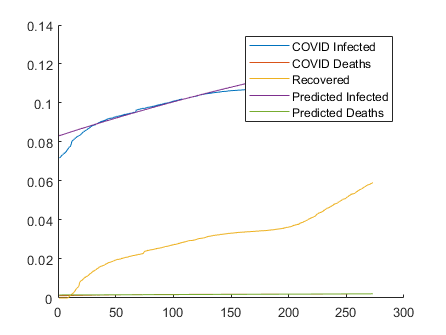


recovered = zeros(size(y(:,3)));
% Assuming COVID takes 7 days to kill / recover, according to CDC
for i=9:length(recovered)
    recovered(i) = coviddata(i-7,1)-coviddata(i-8,1) - (coviddata(i-7,2)-coviddata(i-8,2));
end
recovered = cumsum(recovered);

% create figure
figure;
% hold on to plot data
hold on;
plot(coviddata)
plot(recovered)
plot(y(:,2))
plot(y(:,4))
legend('COVID Infected','COVID Deaths','Recovered','Predicted Infected','Predicted Deaths');
hold off


% plot(Y);
% legend('S','L','I','R','D');
% xlabel('Time')

% Y_fit = siroutput_full(x,t);
% 
% figure(1);

% Make some plots that illustrate your findings.
% TO ADD
